%% Project 2

% An exploration of themes of life, death and love across 
% Grateful Dead studio albums
% Life: Life, lives, live
% Death: Death, dead, decease
% Love: Lover, 


% Create table of songs and album info
song_info=readtable("GD_songs.csv")

song_info = 99×4 table
               Title                            Filename                        Album            Year
    ____________________________    ________________________________    _____________________    ____

    {'100,000 Tons of Steel'   }    {'100,000_Tons_of_Steel.txt'   }    {'In The Dark'      }    1987
    {'Alabama Getaway'         }    {'Alabama_Getaway.txt'         }    {'Go To Heaven'     }    1980
    {'All New Minglewood Blues'}    {'All_New_Minglewood_Blues.txt'}    {'Shakedown Street' }    1978
    {'Alligator'               }    {'Alligator.txt'               }    {'Anthem Of The Sun'}    1968
    {'Althea'                  }    {'Althea.txt'                  }    {'Go To Heaven'     }    1980
    {'Attics Of My Life'       }    {'Attics_of_My_Life.txt'       }    {'American Beauty'  }    1970
    {'Beat it on Down Th


allwords=strings(0,1); % Initialize 
allLyrics={1,height(song_info)}; % Initialize

for i=1:height(song_info)

    filepath=fullfile(strcat("lyrics\",song_info{i,"Filename"})); % filepath to .txt file of lyrics for song i

    allLyrics{i} = fileToArray(filepath); % Add lyrics of song i to cell array of lyrics
    allwords=[allwords;allLyrics{i}]; % Add lyrics of song i to cumulative vector of all words for all songs
end

uniqueWords=unique(allwords); % vector of unique words accross all songs

% Create Matrix A for LSM
for i=1:length(uniqueWords)
    word=uniqueWords(i);
    for j=1:height(song_info)
        song=allLyrics{j};
        A(i,j)=nnz(strcmp(song,word)); % number of times word(i) appears in song(j)   
    end
end

% Create table of word frequency per song from matrix A
words_Freq=array2table(A,"RowNames",uniqueWords,"VariableNames",song_info{:,"Title"});
words_Freq.sum=sum(A,2);
words_Freq=sortrows(words_Freq,"sum",'descend');

% rank of our queries

rank = 2;

%%Query1 (life)
life=["live","lived","livin","living","life","lifetime","alive"];
cosDist_life = semanticAnalysis(A,life,uniqueWords, rank)';
song_info.cosDist_life=cosDist_life; % Add results to table

%%Query2 (death)
death=["dead","drowned","murder","die","fatal","drown","dying","kill","killer","killing"];
cosDist_death = semanticAnalysis(A,death,uniqueWords, rank)';
song_info.cosDist_death=cosDist_death; % Add results to table

%%Query3 (love)
love=["love","loved","lover","lovers","love","lovin","loving","baby","heart","romance","romancin","romantics"];
cosDist_love = semanticAnalysis(A,love,uniqueWords, rank)';
song_info.cosDist_love=cosDist_love; % Add results to table

%%Query4 (Gambling)
gambling=["money","played","jack","lie","lies","whiskey","win","wine","fair","jail","shakedown","shots","fight","drink","drinkin","steal","gin","jailhouse","liquor","losing","pistol"];
cosDist_gambling = semanticAnalysis(A,gambling,uniqueWords,rank )';
song_info.cosDist_gambling=cosDist_gambling; % Add results to table

%%Query5 (Darkness)
darkness=["moon","night","dark","black","cry","broken","darkness","devil","lonely","carrion","dungeon","forsaken","nightmare","nights","nighttime","poisoned","tears"];
cosDist_darkness = semanticAnalysis(A,darkness,uniqueWords, rank)';
song_info.cosDist_darkness=cosDist_darkness; % Add results to table

%%Query6 (Light)
light=["mornin","morning","sun","light","dancing","dance","happy","sunshine","summer","dawn","miracle","laughter","dove","fun"];
cosDist_light = semanticAnalysis(A,light,uniqueWords, rank)';
song_info.cosDist_light=cosDist_light; % Add results to table

% Display table of Cos Dist for each song and theme
song_info(:,["Title","Album","Year","cosDist_life","cosDist_death","cosDist_love","cosDist_gambling","cosDist_darkness","cosDist_light"])

ans = 99×9 table
               Title                        Album            Year    cosDist_life    cosDist_death    cosDist_love    cosDist_gambling    cosDist_darkness    cosDist_light
    ____________________________    _____________________    ____    ____________    _____________    ____________    ________________    ________________    _____________

    {'100,000 Tons of Steel'   }    {'In The Dark'      }    1987      0.99386          0.99998         0.41759           0.99897             0.99999            0.97924   
    {'Alabama Getaway'         }    {'Go To Heaven'     }    1980      0.99528          0.97725         0.59624           0.98679             0.97759           

% Create table to store the mean cosDist for each theme across all songs
avg_cd=table();
avg_cd.life=mean(song_info.cosDist_life);
avg_cd.death=mean(song_info.cosDist_death);
avg_cd.love=mean(song_info.cosDist_love);
avg_cd.gambling=mean(song_info.cosDist_gambling);
avg_cd.darkness=mean(song_info.cosDist_darkness);
avg_cd.light=mean(song_info.cosDist_light);

avg_cd

avg_cd = 1×6 table
     life       death      love      gambling    darkness     light 
    _______    _______    _______    ________    ________    _______

    0.98376    0.97298    0.53747    0.97933     0.97321     0.98278





% Calculate sum of cos Dist for each theme per album
% Normalize by # of songs in album

albums=unique(song_info(:,"Album"));
albums.cd_life(:)=0;
albums.cd_death(:)=0;
albums.cd_love(:)=0;
albums.cd_gambling(:)=0;
albums.cd_darkness(:)=0;
albums.cd_light(:)=0;

for a = 1:height(albums)
    album_name=albums{a,"Album"}{:};

    songs_album_a=song_info(string(song_info.Album) == album_name,:);
    num_songs=height(songs_album_a);

    albums{a,"cd_life"}=sum(songs_album_a.cosDist_life)/num_songs;
    albums{a,"cd_death"}=sum(songs_album_a.cosDist_death)/num_songs;
    albums{a,"cd_love"}=sum(songs_album_a.cosDist_love)/num_songs;
    albums{a,"cd_gambling"}=sum(songs_album_a.cosDist_gambling)/num_songs;
    albums{a,"cd_darkness"}=sum(songs_album_a.cosDist_darkness)/num_songs;
    albums{a,"cd_light"}=sum(songs_album_a.cosDist_light)/num_songs;

end

albums

albums = 13×7 table
                    Album                    cd_life    cd_death    cd_love    cd_gambling    cd_darkness    cd_light
    _____________________________________    _______    ________    _______    ___________    ___________    ________

    {'American Beauty'                  }    0.99422    0.98972     0.49606      0.99335        0.98987      0.98811 
    {'Anthem Of The Sun'                }    0.99349    0.98437     0.52975      0.99002        0.98459      0.99108 
    {'Aoxomoxoa'                        }    0.99522    0.98726     0.52204       0.9924        0.98746      0.99187 
    {'Blues For Allah'                  }    0.99398    0.98601     0.52153      0.99116        0.98621      0.99065 
    {'Built To Last'             

% Life
song_info = sortrows(song_info,"cosDist_life","descend");
albums = sortrows(albums, "cd_life", "descend");

song_info([1:10],["Title","Album","cosDist_life"])

ans = 10×3 table
             Title                              Album                    cosDist_life
    ________________________    _____________________________________    ____________

    {'Just A Little Light' }    {'Built To Last'                    }      0.99999   
    {'Fire On The Mountain'}    {'Shakedown Street'                 }      0.99998   
    {'Casey Jones'         }    {'Workingman's Dead'                }      0.99998   
    {'Money, Money'        }    {'Grateful Dead From The Mars Hotel'}      0.99998   
    {'Morning Dew'         }    {'The Grateful Dead'                }      0.99997   
    {'New Potato Caboose'  }    {'Anthem Of The Sun'                }      0.99997   
    {'Don't Ease Me In'    }    {'Go To Heaven'                     }      0.99996   
    {'Ship of Fools'       }    {'Grateful Dead From The Mars Hotel'}      0.99995   
    {'China Doll'   

albums(:,["Album","cd_life"])

ans = 13×2 table
                    Album                    cd_life
    _____________________________________    _______

    {'Grateful Dead From The Mars Hotel'}    0.99817
    {'Built To Last'                    }    0.99711
    {'Terrapin Station'                 }    0.99675
    {'Aoxomoxoa'                        }    0.99522
    {'Go To Heaven'                     }    0.99501
    {'In The Dark'                      }    0.99493
    {'Wake Of The Flood'                }    0.99483
    {'American Beauty'                  }    0.99422
    {'Blues For Allah'                  }    0.99398
    {'Anthem Of The Sun'                }    0.99349
    {'Workingman's Dead'                }    0.99291
    {'The Grateful Dead'                }    0.97149
    {'Shakedown Street'                 }    0.89313


% Death
song_info = sortrows(song_info,"cosDist_death","descend");
albums = sortrows(albums, "cd_death", "descend");

song_info([1:10],["Title","Album","cosDist_death"])

ans = 10×3 table
               Title                                Album                    cosDist_death
    ____________________________    _____________________________________    _____________

    {'Brokedown Palace'        }    {'American Beauty'                  }             1   
    {'100,000 Tons of Steel'   }    {'In The Dark'                      }       0.99998   
    {'I Will Take You Home'    }    {'Built To Last'                    }       0.99998   
    {'Sunrise'                 }    {'Terrapin Station'                 }       0.99995   
    {'Unbroken Chain'          }    {'Grateful Dead From The Mars Hotel'}       0.99993   
    {'Foolish Heart'           }    {'Built To Last'                    }       0.99993   
    {'Black Muddy River'       }    {'In The Dark'                      }       0.99993   
    {'Rosemary'                }    {'Aoxomoxoa'             

albums(:,["Album","cd_death"])

ans = 13×2 table
                    Album                    cd_death
    _____________________________________    ________

    {'Terrapin Station'                 }    0.99502 
    {'Grateful Dead From The Mars Hotel'}    0.99375 
    {'Wake Of The Flood'                }    0.99358 
    {'Built To Last'                    }    0.99308 
    {'In The Dark'                      }    0.99091 
    {'American Beauty'                  }    0.98972 
    {'Aoxomoxoa'                        }    0.98726 
    {'Blues For Allah'                  }    0.98601 
    {'Anthem Of The Sun'                }    0.98437 
    {'Go To Heaven'                     }    0.98106 
    {'Workingman's Dead'                }    0.98037 
    {'The Grateful Dead'                }    0.94752 
    {'Shakedown Street'                 }    0.85653 



% Love
song_info = sortrows(song_info,"cosDist_love","descend");
albums = sortrows(albums, "cd_love", "descend");

song_info([1:10],["Title","Album","cosDist_love"])

ans = 10×3 table
                  Title                           Album            cosDist_love
    __________________________________    _____________________    ____________

    {'Good Lovin''                   }    {'Shakedown Street' }      0.95068   
    {'Viola Lee Blues'               }    {'The Grateful Dead'}      0.88369   
    {'All New Minglewood Blues'      }    {'Shakedown Street' }      0.79023   
    {'Good Morning Little Schoolgirl'}    {'The Grateful Dead'}      0.77837   
    {'High Time'                     }    {'Workingman's Dead'}      0.76062   
    {'If I Had The World To Give'    }    {'Shakedown Street' }      0.75373   
    {'I Need A Miracle'              }    {'Shakedown Street' }      0.74719   
    {'Caution'                       }    {'Anthem Of The Sun'}      0.70463   
    {'Sitting on Top of the World'   }    {'The Grateful Dead'}      0.67674   


albums(:,["Album","cd_love"])

ans = 13×2 table
                    Album                    cd_love
    _____________________________________    _______

    {'Shakedown Street'                 }    0.68555
    {'The Grateful Dead'                }    0.62894
    {'Go To Heaven'                     }    0.56603
    {'Workingman's Dead'                }    0.55469
    {'Anthem Of The Sun'                }    0.52975
    {'Aoxomoxoa'                        }    0.52204
    {'Blues For Allah'                  }    0.52153
    {'Grateful Dead From The Mars Hotel'}    0.49726
    {'American Beauty'                  }    0.49606
    {'Built To Last'                    }    0.49391
    {'In The Dark'                      }    0.49286
    {'Terrapin Station'                 }    0.47685
    {'Wake Of The Flood'                }     0.4724


% Gambling
song_info = sortrows(song_info,"cosDist_gambling","descend");
albums = sortrows(albums, "cd_gambling", "descend");

song_info([1:10],["Title","Album","cosDist_gambling"])

ans = 10×3 table
                    Title                                     Album                    cosDist_gambling
    ______________________________________    _____________________________________    ________________

    {'When Push Comes to Shove'          }    {'In The Dark'                      }              1     
    {'Alligator'                         }    {'Anthem Of The Sun'                }              1     
    {'Eyes Of The World'                 }    {'Wake Of The Flood'                }              1     
    {'Friend of the Devil'               }    {'American Beauty'                  }        0.99998     
    {'Hell in a Bucket'                  }    {'In The Dark'                      }        0.99998     
    {'U.S. Blues'                        }    {'Grateful Dead From The Mars Hotel'}        0.99997     
    {'Terrapin Station - Lady With a Fan'}    {'

albums(:,["Album","cd_gambling"])

ans = 13×2 table
                    Album                    cd_gambling
    _____________________________________    ___________

    {'Terrapin Station'                 }      0.99744  
    {'Grateful Dead From The Mars Hotel'}      0.99735  
    {'Built To Last'                    }      0.99651  
    {'Wake Of The Flood'                }      0.99579  
    {'In The Dark'                      }      0.99433  
    {'American Beauty'                  }      0.99335  
    {'Aoxomoxoa'                        }       0.9924  
    {'Blues For Allah'                  }      0.99116  
    {'Anthem Of The Sun'                }      0.99002  
    {'Go To Heaven'                     }      0.98882  
    {'Workingman's Dead'                }      0.98751  
    {'The Grateful Dead'                }      0.95961  
    {'Shakedown Street'                 }      0.87401  


% Darkness
song_info = sortrows(song_info,"cosDist_darkness","descend");
albums = sortrows(albums, "cd_darkness", "descend");

song_info([1:10],["Title","Album","cosDist_darkness"])

ans = 10×3 table
               Title                                Album                    cosDist_darkness
    ____________________________    _____________________________________    ________________

    {'Brokedown Palace'        }    {'American Beauty'                  }              1     
    {'100,000 Tons of Steel'   }    {'In The Dark'                      }        0.99999     
    {'I Will Take You Home'    }    {'Built To Last'                    }        0.99997     
    {'Foolish Heart'           }    {'Built To Last'                    }        0.99995     
    {'Rosemary'                }    {'Aoxomoxoa'                        }        0.99994     
    {'Sunrise'                 }    {'Terrapin Station'                 }        0.99994     
    {'Beat it on Down The Line'}    {'The Grateful Dead'                }        0.99992     
    {'Unbroken Chain'          }  

albums(:,["Album","cd_darkness"])

ans = 13×2 table
                    Album                    cd_darkness
    _____________________________________    ___________

    {'Terrapin Station'                 }      0.99513  
    {'Grateful Dead From The Mars Hotel'}      0.99391  
    {'Wake Of The Flood'                }      0.99369  
    {'Built To Last'                    }      0.99323  
    {'In The Dark'                      }      0.99105  
    {'American Beauty'                  }      0.98987  
    {'Aoxomoxoa'                        }      0.98746  
    {'Blues For Allah'                  }      0.98621  
    {'Anthem Of The Sun'                }      0.98459  
    {'Go To Heaven'                     }      0.98135  
    {'Workingman's Dead'                }      0.98063  
    {'The Grateful Dead'                }      0.94793  
    {'Shakedown Street'                 }      0.85711  


% Light
song_info = sortrows(song_info,"cosDist_light","descend");
albums = sortrows(albums, "cd_light", "descend");

song_info([1:10],["Title","Album","cosDist_light"])

ans = 10×3 table
                       Title                               Album            cosDist_light
    ___________________________________________    _____________________    _____________

    {'Alabama Getaway'                        }    {'Go To Heaven'     }       0.99999   
    {'Blow Away'                              }    {'Built To Last'    }       0.99995   
    {'New Speedway Boogie'                    }    {'Workingman's Dead'}       0.99992   
    {'Shakedown Street'                       }    {'Shakedown Street' }       0.99991   
    {'Far From Me'                            }    {'Go To Heaven'     }       0.99991   
    {'Dupree's Diamond Blues'                 }    {'Aoxomoxoa'        }       0.99988   
    {'Doin' That Rag'                         }    {'Aoxomoxoa'        }       0.99982   
    {'The Music Never Stopped'                }    {'Blues For Allah' 

albums(:,["Album","cd_light"])

ans = 13×2 table
                    Album                    cd_light
    _____________________________________    ________

    {'Go To Heaven'                     }    0.99646 
    {'Workingman's Dead'                }    0.99325 
    {'Grateful Dead From The Mars Hotel'}    0.99195 
    {'Aoxomoxoa'                        }    0.99187 
    {'Anthem Of The Sun'                }    0.99108 
    {'Blues For Allah'                  }    0.99065 
    {'Built To Last'                    }    0.99059 
    {'In The Dark'                      }    0.98843 
    {'Terrapin Station'                 }     0.9884 
    {'American Beauty'                  }    0.98811 
    {'Wake Of The Flood'                }    0.98611 
    {'The Grateful Dead'                }    0.98119 
    {'Shakedown Street'                 }    0.91371 



% Conclusions
%- Songs that have strong themes of life also have strong themes of death
% - The Grateful dead did not write many love songs
% - Shakedown Street is an outlier
% - Some albums, American Beauty, contain deeper and more diverse themes
% than others, Workingman's dead.

### Investigating how the cosine similarites change with the rank of the appoximation of our queries


max_rank = size(A,2);
Rank_cosDist_life = zeros(max_rank,max_rank);
Rank_cosDist_death = zeros(max_rank,max_rank);
Rank_cosDist_love = zeros(max_rank,max_rank);
Rank_cosDist_gambling = zeros(max_rank,max_rank);
Rank_cosDist_darkness = zeros(max_rank,max_rank);
Rank_cosDist_light = zeros(max_rank,max_rank);

album_names = table2array(unique(song_info(:,"Album")));

albumsq_life = zeros(max_rank,13);
albumsq_death = zeros(max_rank,13);
albumsq_love = zeros(max_rank,13);
albumsq_gambling = zeros(max_rank,13);
albumsq_darkness = zeros(max_rank,13);
albumsq_light = zeros(max_rank,13);


for i=1:max_rank

    % initialize the rank that we are trying investigating the similarity
    % using
    rank = i;

    %%Query1 (life)
    life=["live","lived","livin","living","life","lifetime","alive"];
    cosDist_life = semanticAnalysis(A,life,uniqueWords,rank)';
    Rank_cosDist_life(:,i) = cosDist_life;
    song_info.cosDist_life=cosDist_life; % Add results to table
    
    %%Query2 (death)
    death=["dead","drowned","murder","die","fatal","drown","dying","kill","killer","killing"];
    cosDist_death = semanticAnalysis(A,death,uniqueWords,rank)';
    Rank_cosDist_death(:,i) = cosDist_death;
    song_info.cosDist_death=cosDist_death; % Add results to table
    
    %%Query3 (love)
    love=["love","loved","lover","lovers","love","lovin","loving","baby","heart","romance","romancin","romantics"];
    cosDist_love = semanticAnalysis(A,love,uniqueWords,rank)';
    Rank_cosDist_love(:,i) = cosDist_love;
    song_info.cosDist_love=cosDist_love; % Add results to table
    
    %%Query4 (Gambling)
    gambling=["money","played","jack","lie","lies","whiskey","win","wine","fair","jail","shakedown","shots","fight","drink","drinkin","steal","gin","jailhouse","liquor","losing","pistol"];
    cosDist_gambling = semanticAnalysis(A,gambling,uniqueWords,rank)';
    Rank_cosDist_gambling(:,i) = cosDist_gambling;
    song_info.cosDist_gambling=cosDist_gambling; % Add results to table
    
    %%Query5 (Darkness)
    darkness=["moon","night","dark","black","cry","broken","darkness","devil","lonely","carrion","dungeon","forsaken","nightmare","nights","nighttime","poisoned","tears"];
    cosDist_darkness = semanticAnalysis(A,darkness,uniqueWords,rank)';
    Rank_cosDist_darkness(:,i) = cosDist_darkness;
    song_info.cosDist_darkness=cosDist_darkness; % Add results to table
    
    %%Query6 (Light)
    light=["mornin","morning","sun","light","dancing","dance","happy","sunshine","summer","dawn","miracle","laughter","dove","fun"];
    cosDist_light = semanticAnalysis(A,light,uniqueWords,rank)';
    Rank_cosDist_light(:,i) = cosDist_light;
    song_info.cosDist_light=cosDist_light; % Add results to table




albums=unique(song_info(:,"Album"));
albums.cd_life(:)=0;
albums.cd_death(:)=0;
albums.cd_love(:)=0;
albums.cd_gambling(:)=0;
albums.cd_darkness(:)=0;
albums.cd_light(:)=0;

for a = 1:height(albums)
    album_name=albums{a,"Album"}{:};

    songs_album_a=song_info(string(song_info.Album) == album_name,:);
        num_songs=height(songs_album_a);

    albums{a,"cd_life"}=sum(songs_album_a.cosDist_life)/num_songs;
    albums{a,"cd_death"}=sum(songs_album_a.cosDist_death)/num_songs;
    albums{a,"cd_love"}=sum(songs_album_a.cosDist_love)/num_songs;
    albums{a,"cd_gambling"}=sum(songs_album_a.cosDist_gambling)/num_songs;
    albums{a,"cd_darkness"}=sum(songs_album_a.cosDist_darkness)/num_songs;
    albums{a,"cd_light"}=sum(songs_album_a.cosDist_light)/num_songs;

end

    albumsq_life(i,:) = albums.cd_life;
    albumsq_death(i,:) = albums.cd_death;
    albumsq_love(i,:) = albums.cd_love;
    albumsq_gambling(i,:) = albums.cd_gambling;
    albumsq_darkness(i,:) = albums.cd_darkness;
    albumsq_light(i,:) = albums.cd_light;

end

array2table(albumsq_life,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

array2table(albumsq_death,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

array2table(albumsq_love,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

array2table(albumsq_gambling,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

array2table(albumsq_darkness,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

array2table(albumsq_light,"VariableNames",album_names)

ans = 99×13 table
    American Beauty    Anthem Of The Sun    Aoxomoxoa    Blues For Allah    Built To Last    Go To Heaven    Grateful Dead From The Mars Hotel    In The Dark    Shakedown Street    Terrapin Station    The Grateful Dead    Wake Of The Flood    Workingman's Dead
    _______________    _________________    _________    _______________    _____________    ____________    _________________________________    ___________    ________________    ________________    _________________    _________________    _________________

              1  

### Plotting based on Rank and theme queried. Colored by album

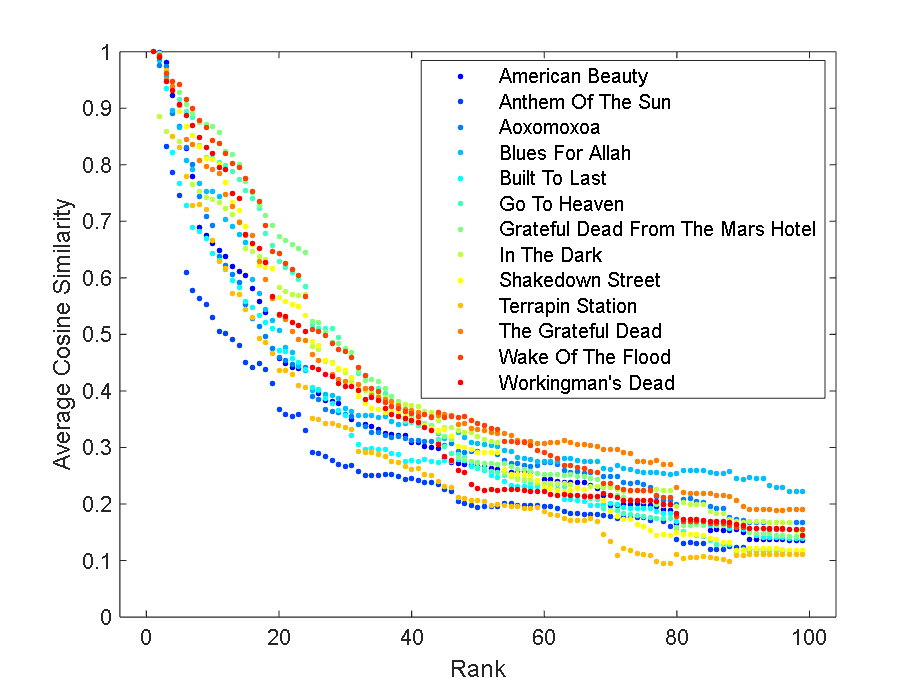

ranks_plot = (1:99)'; % Different ranks
rank = repmat(ranks_plot, 13);
group = repelem(album_names, 99);

obs.life = reshape(albumsq_life, [],1);
obs.death = reshape(albumsq_death,[],1);
obs.love = reshape(albumsq_love,[],1);
obs.gambling = reshape(albumsq_gambling,[],1);
obs.darkness = reshape(albumsq_darkness,[],1);
obs.light = reshape(albumsq_light,[],1);


gscatter(rank,obs.life,group, jet(13), '.',7.5, 'on',"Rank","Average Cosine Similarity")

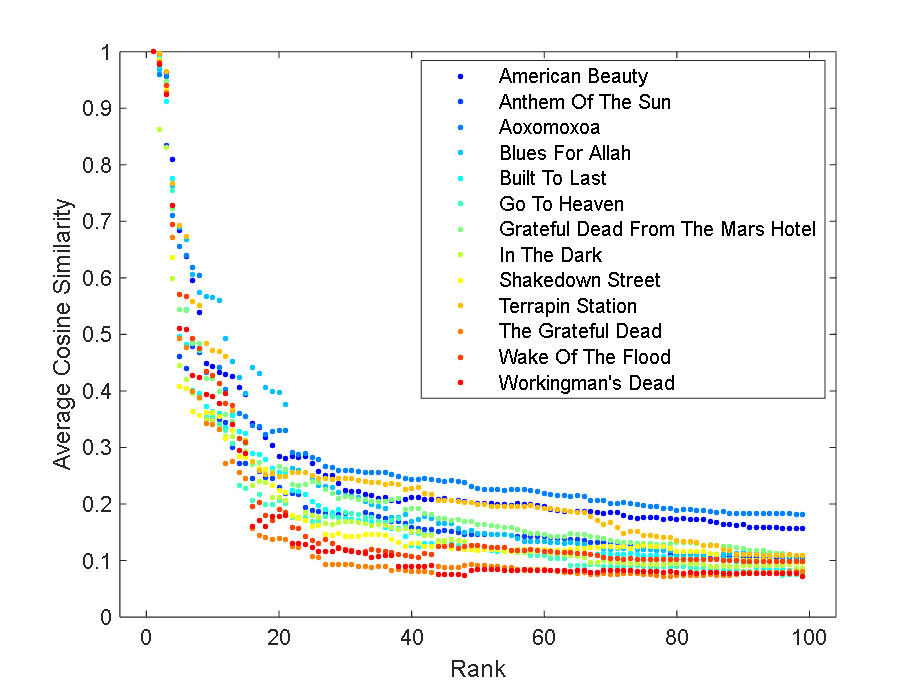

gscatter(rank,obs.death,group, jet(13), '.',7.5 ,'on',"Rank","Average Cosine Similarity")

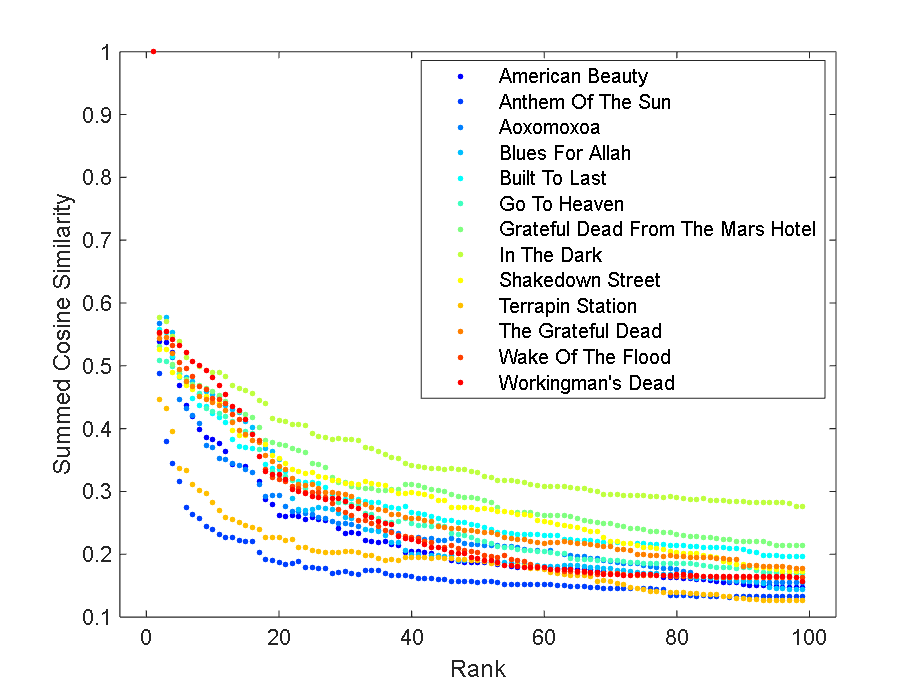

gscatter(rank,obs.love,group, jet(13), '.',7.5 ,'on',"Rank","Summed Cosine Similarity")

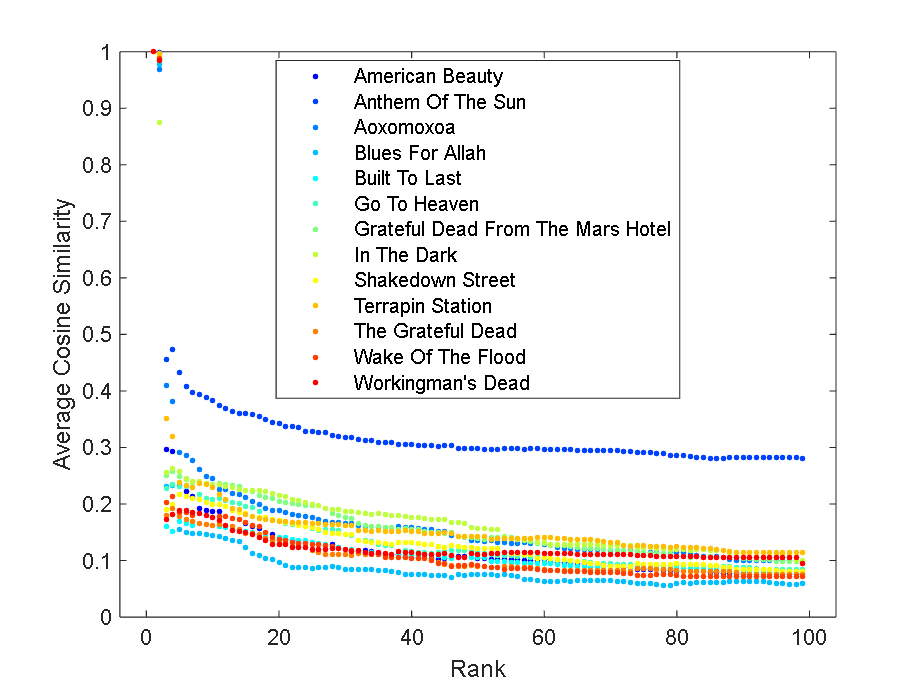

gscatter(rank,obs.gambling,group, jet(13), '.',7.5,  'on',"Rank","Average Cosine Similarity")

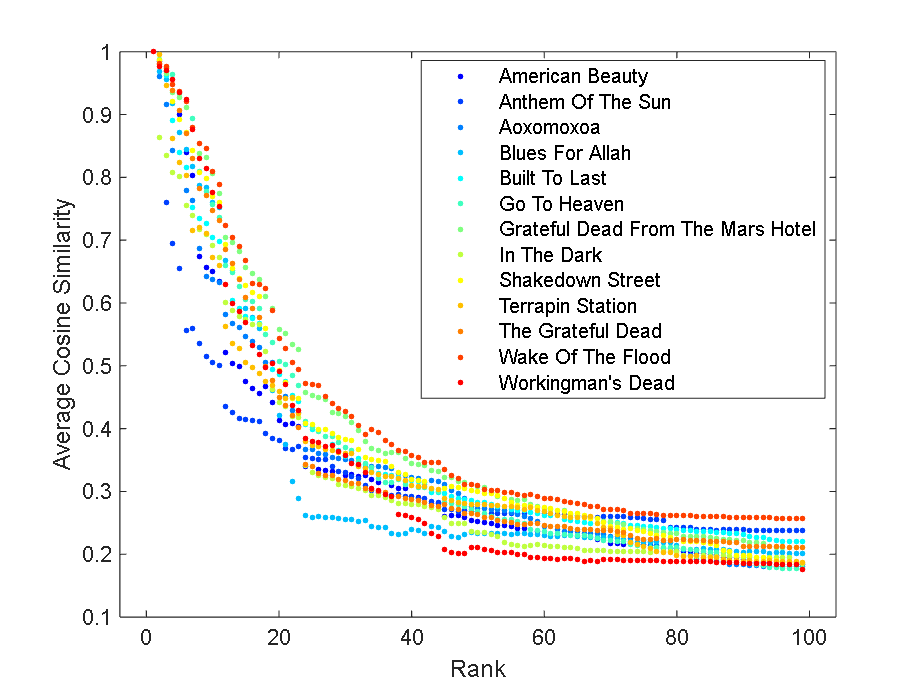

gscatter(rank,obs.darkness,group, jet(13), '.',7.5,  'on',"Rank","Average Cosine Similarity")

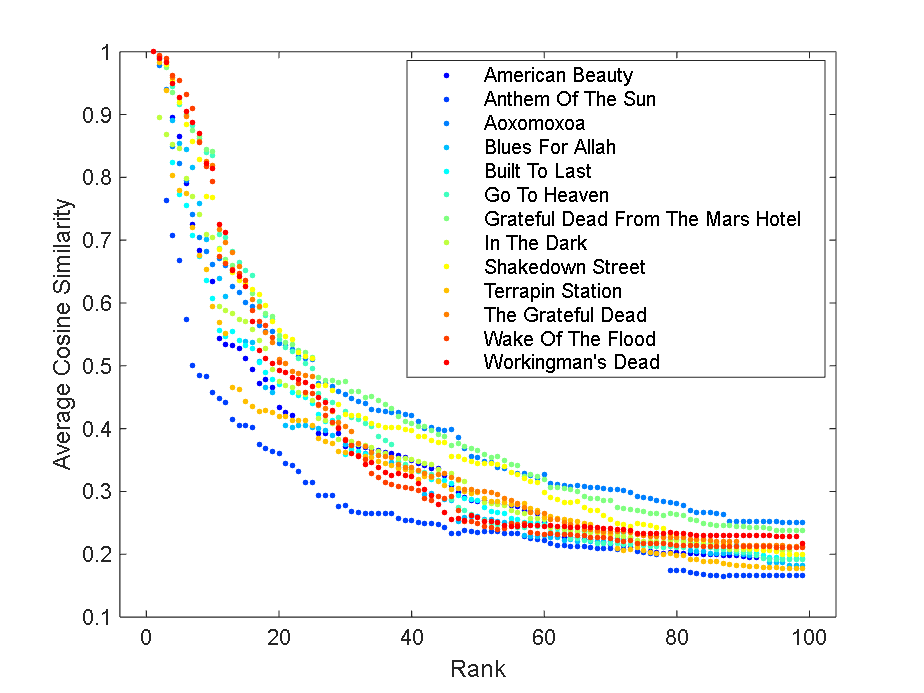

gscatter(rank,obs.light,group, jet(13), '.',7.5,  'on',"Rank","Average Cosine Similarity")

## Functions

%----------------------- Functions --------------------------

function words = fileToArray(filename)
%% Returns cleaned array of words in song specified by "string"

fid=fopen(filename); % open file
words=textscan(fid, '%s'); % read words into cell array
fclose(fid); % close file
words=words{:}; % create string array from cell array
words=lower(words); % convert all characters to lowercase
words=erasePunctuation(words); % remove punctuation characters from strings
words=rmmissing(words); % remove empty elements

ignore=[
  "the";
  "i";
  "you";
  "and";
  "to";
  "a";
  "of";
  "in";
  "on";
  "it";
  "that";
  "for";
  "is";
  "its";
  "this";
  "im";
  "as"
];


for i=1:length(ignore) % remove words specified in ignore array
    words(strcmp(words,ignore(i)))=[];
end

end

function cosDist = semanticAnalysis(A,query,words, rank)

[m,n]=size(A); % number of words, number of songs

%rank=2; % number of singular values to keep in reduced system

[U,S,V]=svd(A);

U1=U(:,[1:rank]);
S1=S([1:rank],[1:rank]);
V1=V(:,[1:rank]);

for i=1:m
    wordsProj(i,:)=U1(i,:)*S1;
end

for i=1:n
    docsProj(:,i)=S1*(V1(i,:))';
end


% Query

q_num=zeros(1,rank);

for i=1:length(query)
    index=find(strcmp(words,query(i)));
    q_num=q_num+wordsProj(index,:);
end

q=q_num/length(query);

for i=1:n
    cosDist(i) = (dot(q',docsProj(:,i)))/(norm(q)*norm(docsProj(:,i)));
end

end
